% Simulation initialization and setup
numSimulations = 1000; % Number of simulations
blockchainObj = bc.vBlockchain(); % Initialize blockchain object

maliciousPercentages = [0.1, 0.2, 0.3, 0.4, 0.5]; % Malicious percentages to test
fixedReputationValue = 0.6; % Fixed reputation value for comparison
% Initialize containers for results across all malicious percentages
dynamicResultsOverall = cell(length(maliciousPercentages), 1);
fixedResultsOverall = cell(length(maliciousPercentages), 1);
% Path to the folder containing all required functions
requiredFolder = fullfile(pwd, 'myFunctions'); % Replace 'myFunctions' with your folder name

% Get all `.m` files in the folder
requiredFilesStruct = dir(fullfile(requiredFolder, '*.m'));
requiredFiles = fullfile(requiredFolder, {requiredFilesStruct.name});

% Start parallel pool
if isempty(gcp('nocreate'))
    pool = parpool; % Start a parallel pool if not already active
    addAttachedFiles(pool, requiredFiles); % Attach the required files to workers
end

% Initialize results storage
allResults_1_4_4 = struct('MaliciousPercentage', [], 'Dynamic', [], 'Fixed', []);

% Parallel loop for each malicious percentage
parfor idx = 1:length(maliciousPercentages)
    maliciousPercentage = maliciousPercentages(idx);
    disp(['Running simulations for malicious percentage: ', num2str(maliciousPercentage * 100), '%']);

    % Initialize temporary storage for results
    dynamicResults_1_4_4 = initializeResultsStruct();
    fixedResults_1_4_4 = initializeResultsStruct();
    for sim = 1:numSimulations
        % Set random seed for reproducibility
        rng(sim);
        % Generate Vreqi, Req, and Vproj outside the loop for consistency
        [Vreqi, Req, Vproj] = runsimulation(blockchainObj, maliciousPercentage);

        % Debug: Start simulation iteration
        disp(['Simulation ', num2str(sim), ': Starting Iteration']);

        % Run dynamic reputation simulation
        disp(['Simulation ', num2str(sim), ': Running Dynamic Configuration']);
        dynamicResults_1_4_4 = runSimulations(blockchainObj, dynamicResults_1_4_4, maliciousPercentage, sim, true, fixedReputationValue, Vreqi, Req, Vproj);

        % Run fixed reputation simulation
        disp(['Simulation ', num2str(sim), ': Running Fixed Configuration']);
        fixedResults_1_4_4 = runSimulations(blockchainObj, fixedResults_1_4_4, maliciousPercentage, sim, false, fixedReputationValue, Vreqi, Req, Vproj);

        % Debug: End simulation iteration
        disp(['Simulation ', num2str(sim), ': Iteration Completed']);
        % Store results for this malicious percentage
        dynamicResultsOverall{idx} = dynamicResults_1_4_4;
        fixedResultsOverall{idx} = fixedResults_1_4_4;
    end


    % Compute average metrics for the current malicious percentage
    dynamicAvgMetrics = calculateAverages(dynamicResults_1_4_4);
    fixedAvgMetrics = calculateAverages(fixedResults_1_4_4);

    % Store results
    allResults_1_4_4(idx).MaliciousPercentage = maliciousPercentage * 100;
    allResults_1_4_4(idx).Dynamic = dynamicAvgMetrics;
    allResults_1_4_4(idx).Fixed = fixedAvgMetrics;

end

Running simulations for malicious percentage: 40%
Running simulations for malicious percentage: 30%
Running simulations for malicious percentage: 20%
Running simulations for malicious percentage: 10%
Simulation 1: Starting Iteration
Simulation 1: Running Dynamic Configuration
Simulation 1: Starting Iteration
Simulation 1: Running Dynamic Configuration
Simulation 1: Starting Iteration
Simulation 1: Running Dynamic Configuration
> In createVreq (line 43)
In 


% Save all results to MAT and CSV files
save('simulation_results_1_4_4.mat', 'allResults_1_4_4');
resultsTable = struct2table(allResults_1_4_4);
writetable(resultsTable, 'simulation_results_1_4_4.csv');
disp('Simulations completed and results saved.');

Simulations completed and results saved.


% Save results
save('dynamic_results_1_4_4.mat', 'dynamicResultsOverall');
save('fixed_results_1_4_4.mat', 'fixedResultsOverall');
disp('Simulations completed and results saved.');

Simulations completed and results saved.



% Calculate average metrics
function avgMetrics = calculateAverages(results)
avgMetrics.AvgSuccessRate = mean(results.offSuccessStatus, 'omitnan');
avgMetrics.AvgInitialReputation = mean(results.initialReputation, 'omitnan');
avgMetrics.AvgUpdateReputation=mean(results.updatedReputation, 'omitnan');
avgMetrics.AvgisMalicious=mean( results.SVproisMalicous,'omitnan');
validEntries = cellfun(@(x) isstruct(x) && isfield(x, 'Offtransaction') && ...
    isfield(x.Offtransaction, 'TransactionsID') && ...
    isfield(x.Offtransaction.TransactionsID, 'totalOffloadingLatency'), ...
    results.SVproresults);
% Extract only valid latency values
latencies = cellfun(@(x) x.Offtransaction.TransactionsID.totalOffloadingLatency, ...
    results.SVproresults(validEntries), 'UniformOutput', true);
avgMetrics.AvgLatency = mean(latencies, 'omitnan');
end

%% Helper Functions

% Initialize results structure
function results = initializeResultsStruct()
results.Vreqiresults = {};
results.Reqresults = {};
results.Vehicularblockchainresults = {};
results.InitialVprojresults = {};
results.VprojwithMaliciousresults = {};
results.CandidateVprojresults = {};
results.VprojisMalicousresults = {};
results.SVproresults = {};
results.offSuccessStatus = [];
results.initialReputation = [];
results.updatedReputation = [];
results.SVproisMalicous = [];
results.updatedVehicularblockchainresults = {};
end

% Run simulation (generalized for both dynamic and fixed)
function results = runSimulations(blockchainObj, results, maliciousPercentage, sim, useDynamicReputation, fixedReputationValue, Vreqi, Req, Vproj)
if useDynamicReputation
    % Dynamic Reputation Simulation
    [Vehicularblockchain, VprojBlockchain, CandidateVproj, SVpro, updatedReputationScore, updatedVehicularblockchain, VProjwithMalicious] = ...
        runDynamicSimulation(blockchainObj, maliciousPercentage, Vreqi, Vproj);
    % Debug output for dynamic simulation
    disp('Dynamic Simulation Outputs:');
    results.Vreqiresults{sim} = Vreqi;
    results.Reqresults{sim} = Req;
    results.Vehicularblockchainresults{sim} = Vehicularblockchain;
    results.InitialVprojresults{sim} = Vproj;
    results.VprojwithMaliciousresults{sim} = VProjwithMalicious;
    results.VprojisMalicousresults{sim} = VProjwithMalicious.isMalicious;
    results.CandidateVprojresults{sim} = CandidateVproj;
    results.updatedVehicularblockchainresults{sim} = updatedVehicularblockchain;
    if isempty(SVpro)
        results.SVproresults{sim} = []; % Set empty for invalid SVpro
    else
        results.SVproresults{sim} = SVpro; % Save valid SVpro
    end
    if ~isempty(SVpro)
        %disp(['Offloading Success Status: ', num2str(SVpro.Offtransaction.TransactionsID.offloadingSuccessstatus)]);
        results.SVproisMalicous(sim) = SVpro.isMalicious;
        results.offSuccessStatus(sim) = SVpro.Offtransaction.TransactionsID.offloadingSuccessstatus;
        results.initialReputation(sim) = CandidateVproj.reputation;
        results.updatedReputation(sim) = updatedReputationScore;
    end
else
    % Fixed Reputation Simulation
    [VProjwithMaliciousFixed, CandidateVprojFixed, SVproFixed, updatedReputationScore, updatedVehicularblockchain] = ...
        runFixedSimulation(blockchainObj, maliciousPercentage, fixedReputationValue, Vreqi, Vproj);
    % Debug output for fixed simulation
    disp('Fixed Simulation Outputs:');
    results.VprojwithMaliciousresults{sim} = VProjwithMaliciousFixed;
    results.VprojisMalicousresults{sim} = VProjwithMaliciousFixed.isMalicious;
    results.CandidateVprojresults{sim} = CandidateVprojFixed;
    if isempty(SVproFixed)
        results.SVproresults{sim} = []; % Set empty for invalid SVpro
    else
        results.SVproresults{sim} = SVproFixed; % Save valid SVpro
    end
    if ~isempty(SVproFixed)
        %disp(['Offloading Success Status: ', num2str(SVproFixed.Offtransaction.TransactionsID.offloadingSuccessstatus)]);
        results.SVproisMalicous(sim) = SVproFixed.isMalicious;
        results.offSuccessStatus(sim) = SVproFixed.Offtransaction.TransactionsID.offloadingSuccessstatus;
        results.initialReputation(sim) = VProjwithMaliciousFixed.reputation;
        results.updatedReputation(sim) = updatedReputationScore;
    end

    results.updatedVehicularblockchainresults{sim} = updatedVehicularblockchain;
end
end


% Dynamic simulation logic
function [Vehicularblockchain, VprojBlockchain, CandidateVproj, SVpro, updatedReputationScore, updatedVehicularblockchain, VProjwithMalicious] = ...
    runDynamicSimulation(blockchainObj, maliciousPercentage, Vreqi, Vproj)

% Assign malicious behavior probabilistically
maliciousProbabilities = struct('high', 0.1, 'intermediate', 0.3, 'low', 0.6);
seed = 123;
VProjwithMalicious = assignMaliciousBehaviorDynamic(Vproj, maliciousPercentage, seed, maliciousProbabilities);

% Add Vproj to Blockchain
blockchainObj = bc.vBlockchain();
Vehicularblockchain = blockchainObj.blockchain;
Vehicularblockchain = AddtoVehicularBlockChain(VProjwithMalicious, Vehicularblockchain, blockchainObj);

% Smart Contract Implementation for Offloading
[VprojBlockchain, CandidateVproj, SVpro, Updated_Vreqi] = SmartContract(Vehicularblockchain, Vreqi);

% Trust Model Development
if ~isempty(SVpro)
    updatedReputationScore = calculateReputation2(SVpro, VprojBlockchain, Vreqi, Updated_Vreqi);
    SVpro.reputation = updatedReputationScore;

    % Update the blockchain with SVpro and Updated_Vreqi
    updatedVehicularblockchain = AddtoVehicularBlockChain(SVpro, Vehicularblockchain, blockchainObj);
    updatedVehicularblockchain = AddtoVehicularBlockChain(Updated_Vreqi, updatedVehicularblockchain, blockchainObj);
else
    % If no provider is selected, maintain the original blockchain
    updatedVehicularblockchain = Vehicularblockchain;
    updatedReputationScore=[];
end
end

% Fixed simulation logic
function [VProjwithMaliciousFixed, CandidateVprojFixed, SVproFixed, updatedReputationScore, updatedVehicularblockchain] = ...
    runFixedSimulation(blockchainObj, maliciousPercentage, fixedReputationValue, Vreqi, Vproj)
seed = 123;
[VProjwithMaliciousFixed, VehicularblockchainFixed] = assignMaliciousVehiclesFixed(Vproj, maliciousPercentage, seed, fixedReputationValue);

[VprojBlockchainFixed, CandidateVprojFixed, SVproFixed, Updated_VreqiFixed] = SmartContract(VehicularblockchainFixed, Vreqi);

if ~isempty(SVproFixed)
    updatedReputationScore = calculateReputation2(SVproFixed, VprojBlockchainFixed, Vreqi, Updated_VreqiFixed);
    SVproFixed.reputation = updatedReputationScore;

    updatedVehicularblockchain = AddtoVehicularBlockChain(SVproFixed, VehicularblockchainFixed, blockchainObj);
    updatedVehicularblockchain = AddtoVehicularBlockChain(Updated_VreqiFixed, updatedVehicularblockchain, blockchainObj);
else
    updatedVehicularblockchain = VehicularblockchainFixed;
    updatedReputationScore=[];
end
end


% Extract malicious percentages
maliciousPercentages = [allResults_1_4_4.MaliciousPercentage]';

% Initialize arrays with NaN to handle missing or inconsistent data
numEntries = numel(allResults_1_4_4);
dynamicSuccessRates = nan(numEntries, 1);
dynamicInitialReputation = nan(numEntries, 1);
dynamicUpdateReputation=nan(numEntries, 1);
dynamicisMalicious=nan(numEntries, 1);
dynamicLatencies = nan(numEntries, 1);
fixedSuccessRates = nan(numEntries, 1);
fixedInitialReputation = nan(numEntries, 1);
fixedUpdateReputation=nan(numEntries, 1);
fixedisMalicious=nan(numEntries, 1);
fixedLatencies = nan(numEntries, 1);

% Extract data using a loop to handle missing fields
for i = 1:numEntries
    if isfield(allResults_1_4_4(i).Dynamic, 'AvgSuccessRate')
        dynamicSuccessRates(i) = allResults_1_4_4(i).Dynamic.AvgSuccessRate;
    end
    if isfield(allResults_1_4_4(i).Dynamic, 'AvgInitialReputation')
        dynamicInitialReputation(i) = allResults_1_4_4(i).Dynamic.AvgInitialReputation;
    end
     if isfield(allResults_1_4_4(i).Dynamic, 'AvgUpdateReputation')
        dynamicUpdateReputation(i) = allResults_1_4_4(i).Dynamic.AvgUpdateReputation;
    end
    if isfield(allResults_1_4_4(i).Dynamic, 'AvgisMalicious')
        dynamicisMalicious(i) = allResults_1_4_4(i).Dynamic.AvgisMalicious;
    end
    if isfield(allResults_1_4_4(i).Dynamic, 'AvgLatency')
        dynamicLatencies(i) = allResults_1_4_4(i).Dynamic.AvgLatency;
    end
    if isfield(allResults_1_4_4(i).Fixed, 'AvgSuccessRate')
        fixedSuccessRates(i) = allResults_1_4_4(i).Fixed.AvgSuccessRate;
    end
    if isfield(allResults_1_4_4(i).Fixed, 'AvgInitialReputation')
        fixedInitialReputation(i) = allResults_1_4_4(i).Fixed.AvgInitialReputation;
    end
     if isfield(allResults_1_4_4(i).Fixed, 'AvgUpdateReputation')
        fixedUpdateReputation(i) = allResults_1_4_4(i).Fixed.AvgUpdateReputation;
    end
    if isfield(allResults_1_4_4(i).Fixed, 'AvgisMalicious')
        fixedisMalicious(i) = allResults_1_4_4(i).Fixed.AvgisMalicious;
    end
    if isfield(allResults_1_4_4(i).Fixed, 'AvgLatency')
        fixedLatencies(i) = allResults_1_4_4(i).Fixed.AvgLatency;
    end
end

% Create a new table with extracted data
resultsTable = table(maliciousPercentages, ...
                     dynamicSuccessRates, dynamicInitialReputation, dynamicUpdateReputation, dynamicisMalicious,dynamicLatencies, ...
                     fixedSuccessRates, fixedInitialReputation,fixedUpdateReputation, fixedisMalicious, fixedLatencies, ...
                     'VariableNames', {'MaliciousPercentage', ...
                                       'DynamicAvgSuccessRate', 'DynamicAvgInitialReputation','DynamiAvgUpdateReputation', 'DynamicAvgisMalicious','DynamicAvgLatency', ...
                                       'FixedAvgSuccessRate', 'FixedAvgInitialReputation', 'FixedAvgUpdateReputation','FixedAvgisMalicious','FixedAvgLatency'});

% % Display the table
% disp(resultsTable);

% Write the table to a CSV file
writetable(resultsTable, 'allResults_1_4_4.csv');
disp('CSV file saved successfully.');

CSV file saved successfully.


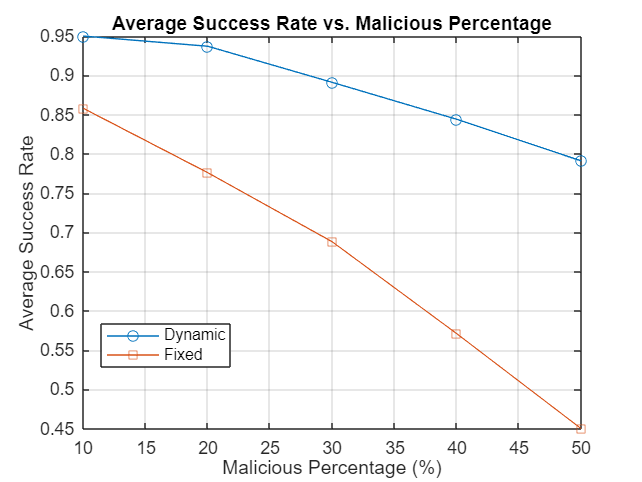

% % Load results
% load('simulation_results_6.mat', 'allResults_6');

% Extract data for plotting
maliciousPercentages = [allResults_1_4_4.MaliciousPercentage];
dynamicSuccessRates = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_1_4_4);
fixedSuccessRates = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_1_4_4);
dynamicInitialReputation = arrayfun(@(x) x.Dynamic.AvgInitialReputation, allResults_1_4_4);
fixedInitialReputation = arrayfun(@(x) x.Fixed.AvgInitialReputation, allResults_1_4_4);
dynamicUpdateReputation=arrayfun(@(x) x.Dynamic.AvgUpdateReputation, allResults_1_4_4);
fixedUpdateReputation=arrayfun(@(x) x.Fixed.AvgUpdateReputation, allResults_1_4_4);
dynamicLatencies = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_1_4_4);
fixedLatencies = arrayfun(@(x) x.Fixed.AvgLatency, allResults_1_4_4);
dynamicisMalicious = arrayfun(@(x) x.Dynamic.AvgisMalicious, allResults_1_4_4);
fixedisMalicious = arrayfun(@(x) x.Fixed.AvgisMalicious, allResults_1_4_4);

% Plot: Average Success Rate vs. Malicious Percentage
figure;
plot(maliciousPercentages, dynamicSuccessRates, '-o', 'DisplayName', 'Dynamic');
hold on;
plot(maliciousPercentages, fixedSuccessRates, '-s', 'DisplayName', 'Fixed');
xlabel('Malicious Percentage (%)');
ylabel('Average Success Rate');
title('Average Success Rate vs. Malicious Percentage');
legend('Location', 'best');
grid on;

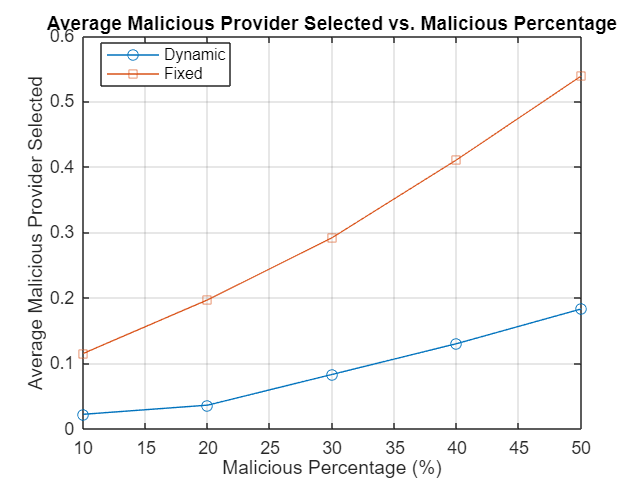


% Plot: Average Initial Reputation vs. Malicious Percentage
figure;
plot(maliciousPercentages, dynamicInitialReputation, '-o', 'DisplayName', 'Dynamic');
hold on;
plot(maliciousPercentages, fixedInitialReputation, '-s', 'DisplayName', 'Fixed');
xlabel('Malicious Percentage (%)');
ylabel('AvgInitialReputation');
title('AvgInitialReputation vs. Malicious Percentage');
legend('Location', 'best');
grid on;

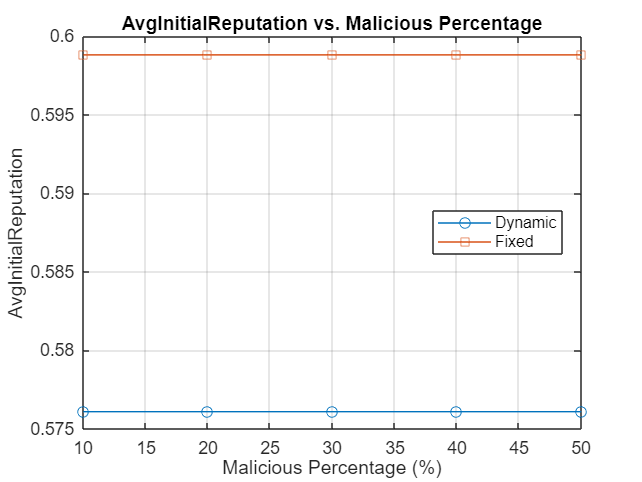


% Plot: Average Updated Reputationvs. Malicious Percentage
figure;
plot(maliciousPercentages, dynamicUpdateReputation, '-o', 'DisplayName', 'Dynamic');
hold on;
plot(maliciousPercentages, fixedUpdateReputation, '-s', 'DisplayName', 'Fixed');
xlabel('Malicious Percentage (%)');
ylabel('AvgUpdateReputation');
title('AvgUpdateReputation vs. Malicious Percentage');
legend('Location', 'best');
grid on;

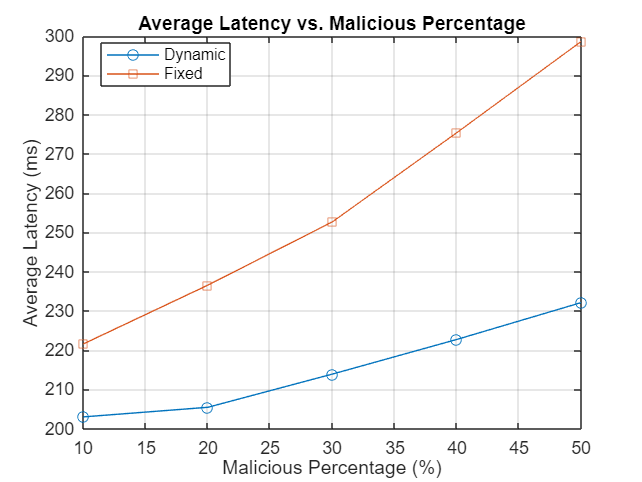


% Plot: Average Latency vs. Malicious Percentage
figure;
plot(maliciousPercentages, dynamicLatencies, '-o', 'DisplayName', 'Dynamic');
hold on;
plot(maliciousPercentages, fixedLatencies, '-s', 'DisplayName', 'Fixed');
xlabel('Malicious Percentage (%)');
ylabel('Average Latency (ms)');
title('Average Latency vs. Malicious Percentage');
legend('Location', 'best');
grid on;

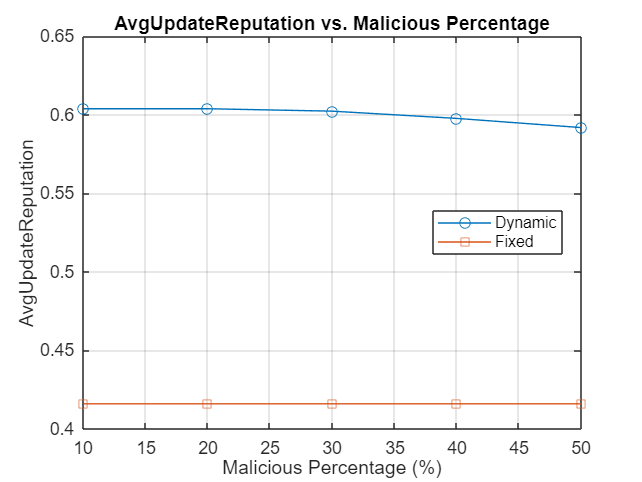


% Plot: Average isMalicious Selected vs. Malicious Percentage
figure;
plot(maliciousPercentages, dynamicisMalicious, '-o', 'DisplayName', 'Dynamic');
hold on;
plot(maliciousPercentages, fixedisMalicious, '-s', 'DisplayName', 'Fixed');
xlabel('Malicious Percentage (%)');
ylabel('Average Malicious Provider Selected');
title('Average Malicious Provider Selected vs. Malicious Percentage');
legend('Location', 'best');
grid on;


% Save plots to files
saveas(1, 'AvgSuccessRate_vs_MaliciousPercentage_1_4_4.png');
saveas(2, 'AvgInitialReputation_vs_MaliciousPercentage_1_4_4.png');
saveas(2, 'AvgUpdateReputation_vs_MaliciousPercentage_1_4_4.png');
saveas(3, 'AvgLatency_vs_MaliciousPercentage_1_4_4.png');
saveas(3, 'AvgisMalicious_vs_MaliciousPercentage_1_4_4.png');

disp('Plots generated and saved.');

Plots generated and saved.


% Extract metrics for both configurations
dynamicSuccessRates = arrayfun(@(x) x.Dynamic.AvgSuccessRate, allResults_4_randomAssign);
fixedSuccessRates = arrayfun(@(x) x.Fixed.AvgSuccessRate, allResults_4_randomAssign);

dynamicInitialReputation = arrayfun(@(x) x.Dynamic.AvgTrustScore, allResults_4_randomAssign);
fixedInitialReputation = arrayfun(@(x) x.Fixed.AvgTrustScore, allResults_4_randomAssign);

dynamicLatencies = arrayfun(@(x) x.Dynamic.AvgLatency, allResults_4_randomAssign);
fixedLatencies = arrayfun(@(x) x.Fixed.AvgLatency, allResults_4_randomAssign);

% Initialize arrays to store results
successRatePValues = zeros(length(maliciousPercentages), 1);
trustScorePValues = zeros(length(maliciousPercentages), 1);
latencyPValues = zeros(length(maliciousPercentages), 1);

% Perform paired t-tests for each malicious percentage
for i = 1:length(maliciousPercentages)
    % Success Rate
    [~, successRatePValues(i)] = ttest(dynamicSuccessRates(i), fixedSuccessRates(i));
    
    % Trust Score
    [~, trustScorePValues(i)] = ttest(dynamicInitialReputation(i), fixedInitialReputation(i));
    
    % Latency
    [~, latencyPValues(i)] = ttest(dynamicLatencies(i), fixedLatencies(i));
end

% Display results
disp('P-Values for Success Rate:');
disp(successRatePValues);

disp('P-Values for Trust Score:');
disp(trustScorePValues);

disp('P-Values for Latency:');
disp(latencyPValues);

% Interpret Results
significanceThreshold = 0.05;
significantSuccessRate = find(successRatePValues < significanceThreshold);
significantTrustScore = find(trustScorePValues < significanceThreshold);
significantLatency = find(latencyPValues < significanceThreshold);

disp('Malicious Percentages with Significant Differences:');
disp('For Success Rate:');
disp(maliciousPercentages(significantSuccessRate));
disp('For Trust Score:');
disp(maliciousPercentages(significantTrustScore));
disp('For Latency:');
disp(maliciousPercentages(significantLatency));

figure;
bar(maliciousPercentages, [dynamicSuccessRates', fixedSuccessRates'], 'grouped');
hold on;

% Add significance stars
for i = 1:length(maliciousPercentages)
    if successRatePValues(i) < 0.05
        text(maliciousPercentages(i), max(dynamicSuccessRates(i), fixedSuccessRates(i)) + 0.05, '*', 'FontSize', 14, 'HorizontalAlignment', 'center');
    end
end

xlabel('Malicious Percentage (%)');
ylabel('Average Success Rate');
legend({'Dynamic', 'Fixed'}, 'Location', 'southwest');
title('Average Success Rate with Significance Markers');
grid on;

% Example: Plot distributions for Success Rates, Trust Scores, and Latencies

% Success Rates Histogram
figure;
subplot(3, 1, 1);
histogram(dynamicSuccessRates, 'Normalization', 'pdf', 'FaceAlpha', 0.7, 'DisplayName', 'Dynamic');
hold on;
histogram(fixedSuccessRates, 'Normalization', 'pdf', 'FaceAlpha', 0.7, 'DisplayName', 'Fixed');
xlabel('Success Rate');
ylabel('Probability Density');
legend('Dynamic', 'Fixed');
title('Distribution of Success Rates');
grid on;

% Trust Scores Histogram
subplot(3, 1, 2);
histogram(dynamicInitialReputation, 'Normalization', 'pdf', 'FaceAlpha', 0.7, 'DisplayName', 'Dynamic');
hold on;
histogram(fixedInitialReputation, 'Normalization', 'pdf', 'FaceAlpha', 0.7, 'DisplayName', 'Fixed');
xlabel('Trust Score');
ylabel('Probability Density');
legend('Dynamic', 'Fixed');
title('Distribution of Trust Scores');
grid on;

% Latencies Histogram
subplot(3, 1, 3);
histogram(dynamicLatencies, 'Normalization', 'pdf', 'FaceAlpha', 0.7, 'DisplayName', 'Dynamic');
hold on;
histogram(fixedLatencies, 'Normalization', 'pdf', 'FaceAlpha', 0.7, 'DisplayName', 'Fixed');
xlabel('Latency');
ylabel('Probability Density');
legend('Dynamic', 'Fixed');
title('Distribution of Latencies');
grid on;


% Test for Normality of Dynamic and Fixed Success Rates
[h_dynamic, p_dynamic] = kstest(dynamicSuccessRates);
[h_fixed, p_fixed] = kstest(fixedSuccessRates);

disp('Dynamic Success Rate Normality Test (KS):');
disp(['Hypothesis rejected (not normal): ', num2str(h_dynamic)]);
disp(['p-value: ', num2str(p_dynamic)]);

disp('Fixed Success Rate Normality Test (KS):');
disp(['Hypothesis rejected (not normal): ', num2str(h_fixed)]);
disp(['p-value: ', num2str(p_fixed)]);
% Success Rate Distribution with Normal Fit
figure;
histogram(dynamicSuccessRates, 'Normalization', 'pdf', 'FaceAlpha', 0.7, 'DisplayName', 'Dynamic');
hold on;
mu = mean(dynamicSuccessRates);
sigma = std(dynamicSuccessRates);
x = linspace(min(dynamicSuccessRates), max(dynamicSuccessRates), 100);
y = normpdf(x, mu, sigma);
plot(x, y, 'r-', 'LineWidth', 2, 'DisplayName', 'Normal Fit');
xlabel('Success Rate');
ylabel('Probability Density');
legend('Dynamic', 'Normal Fit');
title('Success Rate Distribution with Normal Fit (Dynamic)');
grid on;

